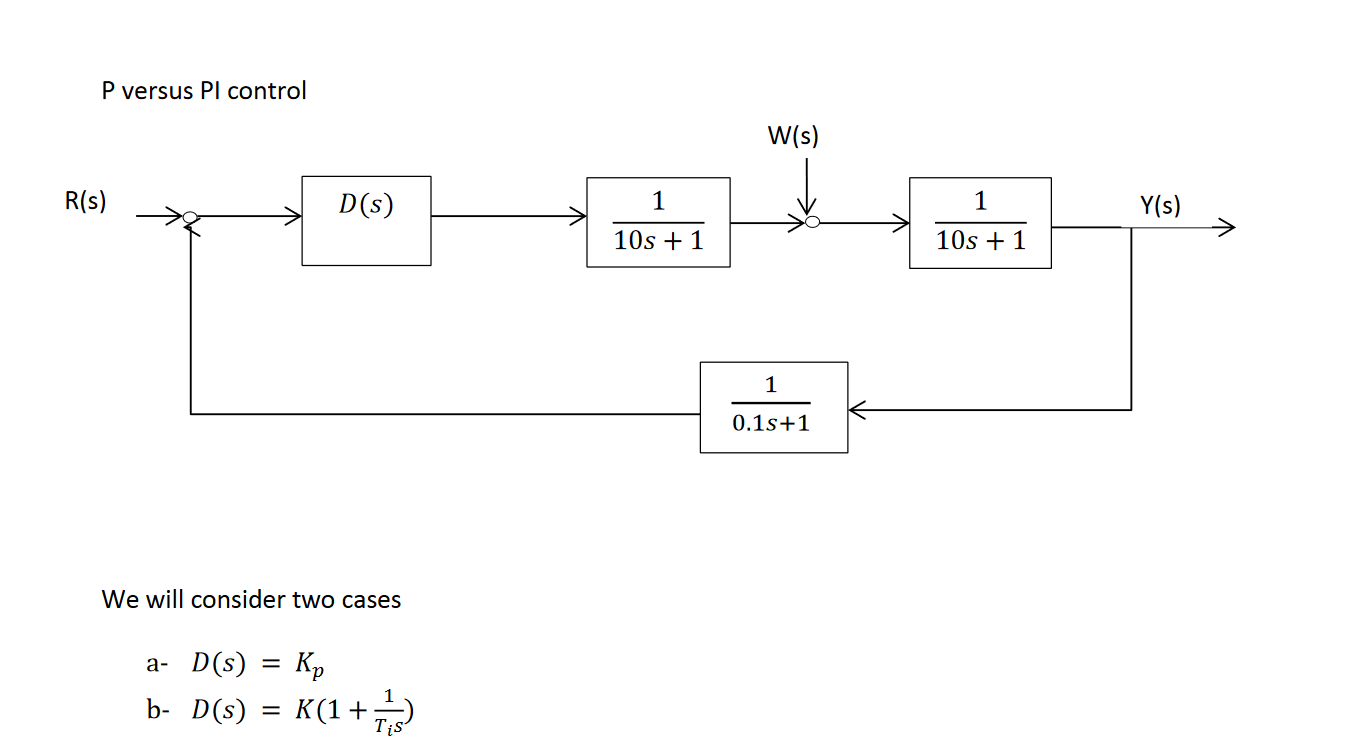

## 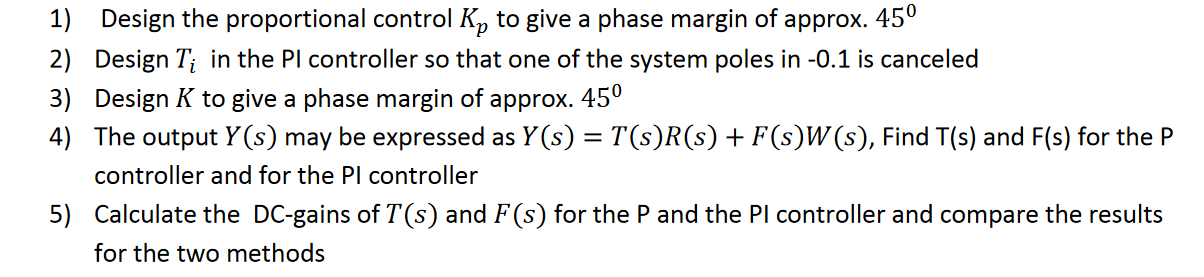

## 1)

direct tf: $K_p \cdot \frac{1}{100s^2 +20s+1}$

close tf: $\frac{\frac{K_p }{100s^2 +20s+1}}{1+\frac{K_p }{100s^2 +20s+1}\cdot \frac{1}{0\ldotp 1s+1}}=$

open loop: $\frac{K_p }{100s^2 +20s+1}\cdot \frac{1}{0\ldotp 1s+1}$ plottes i margin man finder -135 grader phase eftersom det giver et PM på 45 ved den frekvens finder man dB og udregner en propertional konstant Kp så man har den PM på 45


$$16\ldotp 3=20\log \left(\mathrm{Kp}\right)\Rightarrow \mathrm{Kp}=6\ldotp 53$$


solve(16.3==20*log10(Kp),Kp)

$$ans = 10^{163/200}$$

var = vpa(ans)

$$var = 6.5313055264747235525532684450282$$

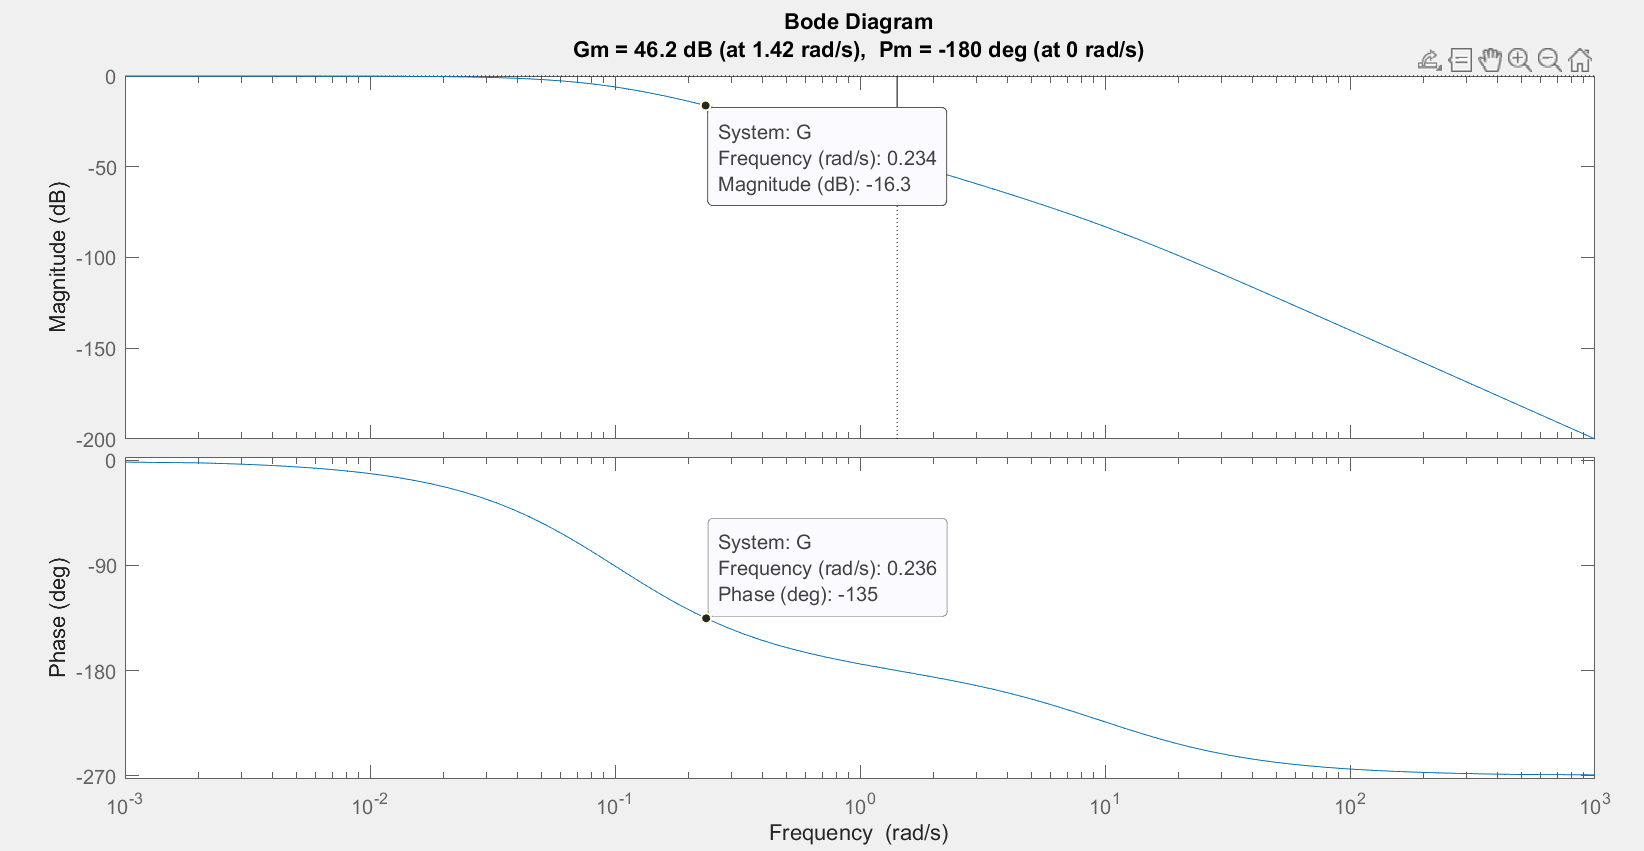

## 2)

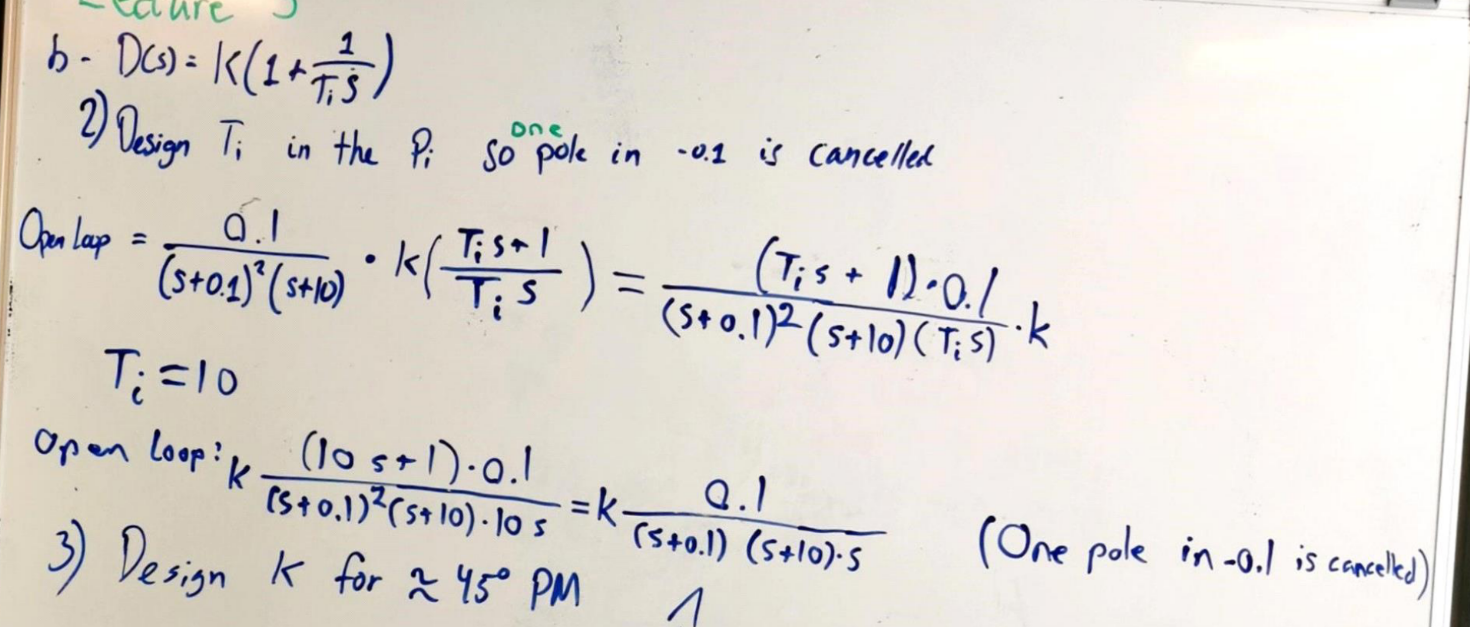

syms s k
k * (((10*s+1)*0.1)/((s+0.1)^2*(s+10)*10*s));
vpa((10*s+1)*0.1)

$$ans = s+0.1$$

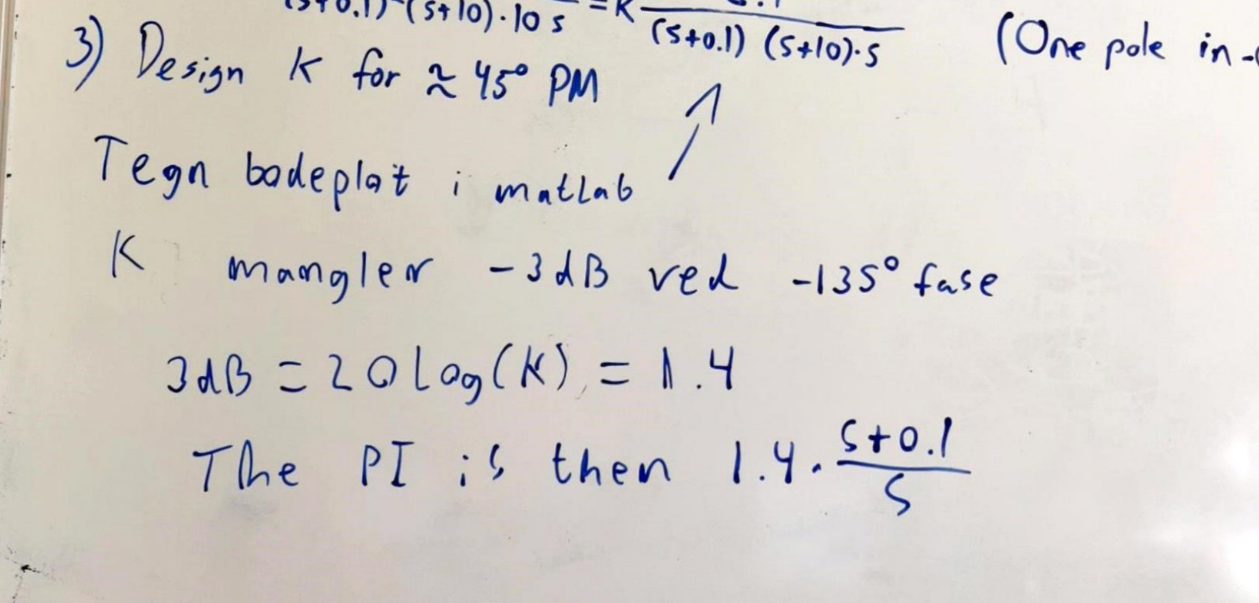

## 4)

T(s) og F(s) for propertional controlleren.


$$T\left(s\right)=\frac{\;Y\left(s\right)}{R\left(s\right)}\frac{\frac{K_p }{100s^2 +20s+1}}{1+\frac{K_p }{100s^2 +20s+1}\cdot \frac{1}{0\ldotp 1s+1}}$$



$$F\left(s\right)=\frac{\;Y\left(s\right)}{W\left(s\right)}\frac{\;\mathrm{direct}\;\mathrm{term}\;w\to y}{1+\mathrm{open}\;\mathrm{loop}}=\frac{\frac{1}{10s+1}}{1+\frac{K_p }{100s^2 +20s+1}\cdot \frac{1}{0\ldotp 1s+1}}$$


Hernæst det samme for PI bare ind sæt det andet i stedet for Kp

For DC så skal man udregne $\lim_{s\to 0} T\left(s\right)$og $\lim_{s\to 0\;} \;F\left(s\right)$for både propertional og PI controlleren.

Så for man disse resultater udfra limit og ser dermed at: